%{ 
Lab Session - 3
Assignment
Ques- 05
Author- Aditya Arun Ghorpade
Roll no.- 254161012
%}

% 101 consecutive daily close prices
close_price=[22119.3, 22082.65, 22337.3, 22544.7, 22552.5, 22460.3, 22497.9, 22470.5, 22397.2, 22508.75, 22834.3, 22907.6, 23190.65, 23350.4, 23658.35, 23668.65, 23486.85, 23591.95, 23519.35, 23165.7, 23332.35, 23250.1, 22904.45, 22161.6, 22535.85, 22399.15, 22828.55, 23328.55, 23437.2, 23851.65, 24125.55, 24167.25, 24328.95, 24246.7, 24039.35, 24328.5, 24335.95, 24334.2, 24346.7, 24461.15, 24379.6, 24414.4, 24273.8, 24008.0, 24924.7, 24578.35, 24666.9, 25062.1, 25019.8, 24945.45, 24683.9, 24813.45, 24609.7, 24853.15, 25001.15, 24826.2, 24752.45, 24833.6, 24750.7, 24716.6, 24542.5, 24620.2, 24750.9, 25003.05, 25103.2, 25104.25, 25141.4, 24888.2, 24718.6, 24946.5, 24853.4, 24812.05, 24793.25, 25112.4, 24971.9, 25044.35, 25244.75, 25549.0, 25637.8, 25517.05, 25541.8, 25453.4, 25405.3, 25461.0, 25461.3, 25522.5, 25476.1, 25355.25, 25149.85, 25082.3, 25195.8, 25212.05, 25111.45, 24968.4, 25090.7, 25060.9, 25219.9, 25062.1, 24837.0, 24680.9, 28534.1]

close_price = 1.0e+04 *

    2.2119    2.2083    2.2337    2.2545    2.2553    2.2460    2.2498    2.2471    2.2397    2.2509    2.2834    2.2908    2.3191    2.3350    2.3658    2.3669    2.3487    2.3592    2.3519    2.3166    2.3332    2.3250    2.2904    2.2162    2.2536    2.2399    2.2829    2.3329    2.3437    2.3852    2.4126    2.4167    2.4329    2.4247    2.4039    2.4329    2.4336    2.4334    2.4347    2.4461    2.4380    2.4414    2.4274    2.4008    2.4925    2.4578    2.4667    2.5062    2.5020    2.4945


days = 0:100;

%Part a
x = 0:5:100; % Nodes
y = close_price(1:5:end); % Price every fifth day

p = polyfit(x,y,20) % Polynomial of degree 20

p = 1.0e+05 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0002   -0.0026    0.0295   -0.2353    1.2473   -3.8924    5.3189    0.2230



x_points=0:1:100

x_points =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49



y_interp = polyval(p, x_points) % Evaluate

y_interp = 1.0e+05 *

    0.2230    2.6885    2.3010    1.3494    0.6135    0.2252    0.0949    0.1002    0.1508    0.1989    0.2283    0.2399    0.2410    0.2385    0.2367    0.2367    0.2379    0.2390    0.2387    0.2367    0.2333    0.2293    0.2257    0.2233    0.2227    0.2240    0.2268    0.2306    0.2346    0.2383    0.2413    0.2432    0.2441    0.2442    0.2439    0.2433    0.2428    0.2426    0.2427    0.2432    0.2438    0.2445    0.2451    0.2455    0.2457    0.2458    0.2458    0.2458    0.2460    0.2463


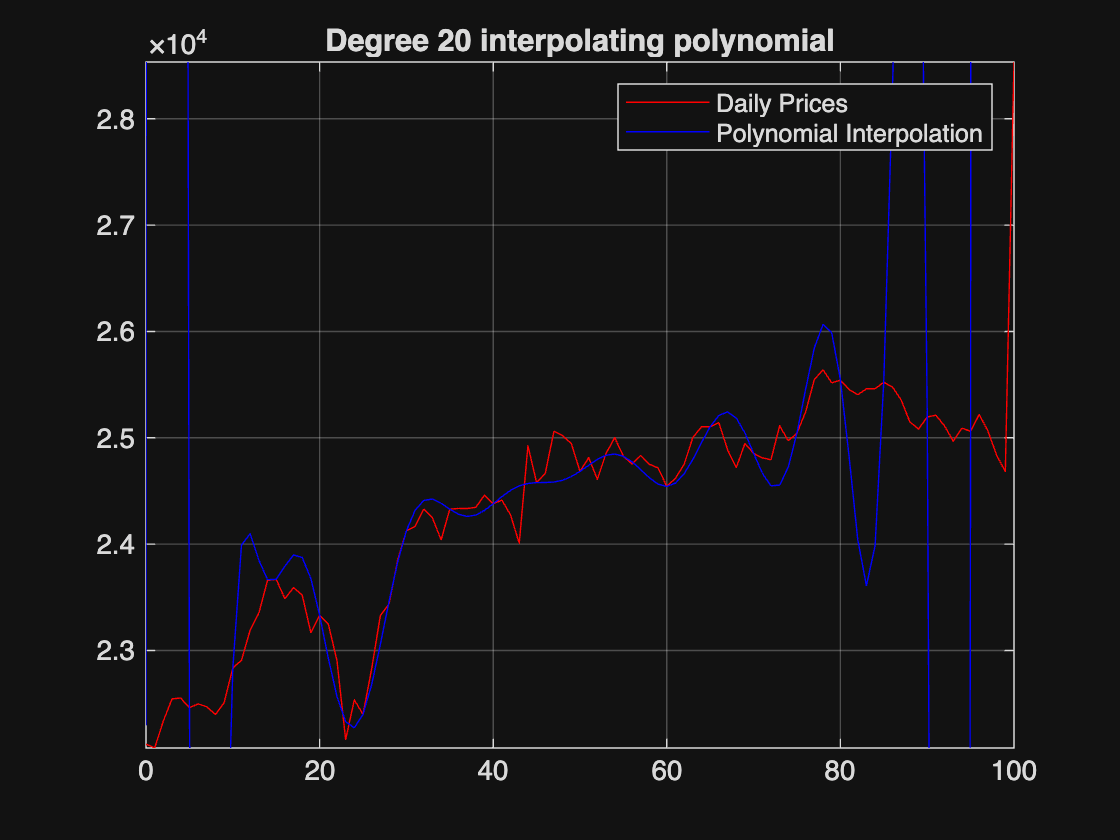


figure;
plot(days, close_price, 'r','DisplayName', 'Daily Prices');
hold on;
plot(x_points, y_interp,'b', 'DisplayName', 'Polynomial Interpolation');
xlim([0 100]);
ylim([min(close_price) max(close_price)]);
title('Degree 20 interpolating polynomial');
legend show;
grid on;


% Calculting Error
errors = abs(y_interp - close_price);
max_err = max(errors)

max_err = 7.5535e+05

disp(['Maximum interpolation error= ', num2str(max_err)])

Maximum interpolation error= 755348.6964




%{
In Polynomial Interpolation maximum interpolation error = 7.5535e+05.
From the plot we can observe, the Runge phenomenon is evident at both
tails.
%}

% Part b - Natural Cubic Spline
y_spline = spline(x,y,x_points)

y_spline = 1.0e+04 *

    2.2119    2.2235    2.2318    2.2378    2.2423    2.2460    2.2499    2.2548    2.2614    2.2707    2.2834    2.3000    2.3187    2.3375    2.3542    2.3669    2.3736    2.3738    2.3673    2.3539    2.3332    2.3062    2.2775    2.2530    2.2386    2.2399    2.2607    2.2957    2.3376    2.3790    2.4126    2.4327    2.4412    2.4416    2.4376    2.4329    2.4302    2.4298    2.4313    2.4341    2.4380    2.4423    2.4467    2.4510    2.4548    2.4578    2.4599    2.4614    2.4629    2.4650


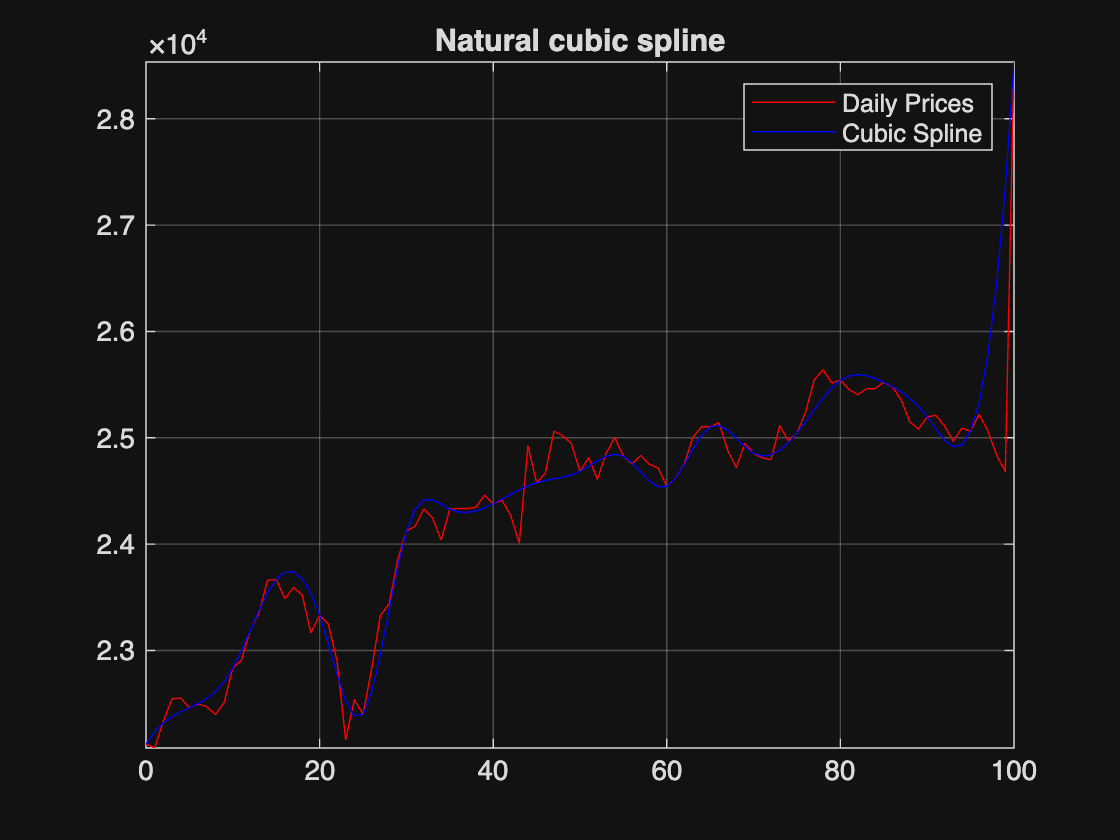


figure;
plot(days, close_price, 'r','DisplayName', 'Daily Prices')
hold on;
plot(x_points, y_spline,'b', 'DisplayName', 'Cubic Spline');
xlim([0 100]);
ylim([min(close_price) max(close_price)]);
title('Natural cubic spline')
legend show;
grid on;


% Calculting Error
errors = abs(y_spline - close_price);
max_err = max(errors)

max_err = 2.6684e+03

disp(['Maximum interpolation error= ', num2str(max_err)])

Maximum interpolation error= 2668.4466




%{
In Natural cubic spline maximum interpolation error = 2.6684e+03
From the plot we can observe, the Runge phenomenon is not present
%}

%{
Accuracy: The cubic spline interpolation provides a more accurate representation 
of the data with a lower maximum error compared to the high error from 
polynomial interpolation.

Behavior: Polynomial interpolation can exhibit Runge phenomenon,
especially with high-degree polynomials, while cubic splines maintain
smoothness and continuity.
%}